clear;
clc;

**Representação do sistema:**

imagem = imread('sistema-suspensao.jpg');
disp('Figura 1 - Esquema da suspensão veicular.');

Figura 1 - Esquema da suspensão veicular.


imshow(imagem);

**Diagrama de corpo livre:**

imagem = imread('DCL.jpg');
disp('Figura 2 - Diagrama de corpo livre.');

Figura 2 - Diagrama de corpo livre.


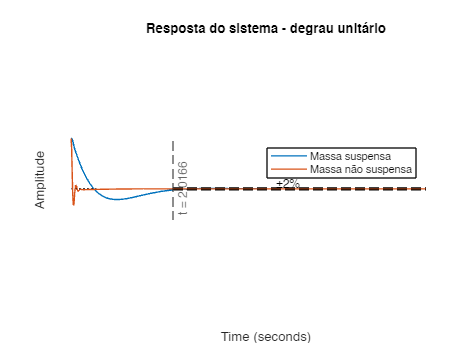

imshow(imagem);

**Variáveis do sistema:**

syms Ms Mn;                                 % Simbologia de massa: suspensa e não supensa
syms Ks Kt;                                 % Simbologia de rigidez: suspensão e pneu
syms Cs;                                    % Simbologia de amortecimento linear viscoso: suspensão
syms u U;                                   % Simbologia de entradas: disturbios no tempo e em Laplace
syms s t;                                   % Laplace frequencia complexa 
syms z0 z1 z2 v0 v1 v2 a0 a1 a2;            % Deslocamentos, velocidades e acelerações no tempo
syms Z0 Z1 Z2;                              % Deslocamentos, velocidades e acelerações Laplace

disp('Ms = massa suspensa; Mn = massa não suspensa');

Ms = massa suspensa; Mn = massa não suspensa


disp('Ks = rigidez da suspesão; Kt = rigidez do pneu');

Ks = rigidez da suspesão; Kt = rigidez do pneu


disp('Cs = amortecimento linear viscoso');

Cs = amortecimento linear viscoso


disp('z0, z1, z2 = deslocamentos lineares')

z0, z1, z2 = deslocamentos lineares


**Equações dinâmicas do movimento (2ª lei de Newton):**

disp(' '); disp('Equações do movimento:');

 
Equações do movimento:



Eq1 = -Cs*(v2-v1) - Ks*(z2-z1) + u - Ms*a2; disp(Eq1);

$$u-\mathrm{Ms}\,a_{2}+\mathrm{Cs}\,\left(v_{1}-v_{2}\right)+\mathrm{Ks}\,\left(z_{1}-z_{2}\right)$$

Eq2 = Cs*(v2-v1) + Ks*(z2-z1) + Kt*(z0-z1) - u - Mn*a1; disp(Eq2);

$$\mathrm{Kt}\,\left(z_{0}-z_{1}\right)-\mathrm{Mn}\,a_{1}-\mathrm{Cs}\,\left(v_{1}-v_{2}\right)-\mathrm{Ks}\,\left(z_{1}-z_{2}\right)-u$$

**Transformadas de Laplace:**

disp(' '); disp('Transformadas de Laplace das equações do movimento:');

 
Transformadas de Laplace das equações do movimento:



Eq1_s = (Cs*s+Ks)*Z1 + (-(Ms*s^2)-(Cs*s)-Ks)*Z2 == U; disp(Eq1_s);

$$Z_{1}\,\left(\mathrm{Ks}+\mathrm{Cs}\,s\right)-Z_{2}\,\left(\mathrm{Ms}\,s^{2}+\mathrm{Cs}\,s+\mathrm{Ks}\right)=U$$

Eq2_s = (-(Mn*s^2)-(Cs*s)-Ks-Kt)*Z1 + (Cs*s+Ks)*Z2 == U - Kt*Z0; disp(Eq2_s);

$$Z_{2}\,\left(\mathrm{Ks}+\mathrm{Cs}\,s\right)-Z_{1}\,\left(\mathrm{Mn}\,s^{2}+\mathrm{Cs}\,s+\mathrm{Ks}+\mathrm{Kt}\right)=U-\mathrm{Kt}\,Z_{0}$$


disp(' '); disp('Forma matricial:');

 
Forma matricial:


vars = [Z1, Z2];    % variáveis de interesse
[A,B] = equationsToMatrix([Eq1_s, Eq2_s],vars);
disp(A); disp(vars); disp(B);

$$\left(\begin{array}{cc} \mathrm{Ks}+\mathrm{Cs}\,s & -\mathrm{Ms}\,s^{2}-\mathrm{Cs}\,s-\mathrm{Ks}\\ -\mathrm{Mn}\,s^{2}-\mathrm{Cs}\,s-\mathrm{Ks}-\mathrm{Kt} & \mathrm{Ks}+\mathrm{Cs}\,s \end{array}\right)$$

$$\left(\begin{array}{cc} Z_{1} & Z_{2} \end{array}\right)$$

$$\left(\begin{array}{c} U\\ U-\mathrm{Kt}\,Z_{0} \end{array}\right)$$


disp(' '); disp('Resolvendo o determinante de [A] encontra-se Δ:');

 
Resolvendo o determinante de [A] encontra-se Δ:


delta = det(A); disp(delta);

$$-\mathrm{Ks}\,\mathrm{Kt}-\mathrm{Cs}\,\mathrm{Kt}\,s-\mathrm{Cs}\,\mathrm{Mn}\,s^{3}-\mathrm{Cs}\,\mathrm{Ms}\,s^{3}-\mathrm{Ks}\,\mathrm{Mn}\,s^{2}-\mathrm{Ks}\,\mathrm{Ms}\,s^{2}-\mathrm{Kt}\,\mathrm{Ms}\,s^{2}-\mathrm{Mn}\,\mathrm{Ms}\,s^{4}$$

disp(' '); disp('A matriz abaixo é usada para encontrar o determinante para Z1:');

 
A matriz abaixo é usada para encontrar o determinante para Z1:


AmodificadaZ1 = A;
AmodificadaZ1(:, 1) = B;    % Substituindo a primeira coluna de [A] pela matriz B
disp(AmodificadaZ1);

$$\left(\begin{array}{cc} U & -\mathrm{Ms}\,s^{2}-\mathrm{Cs}\,s-\mathrm{Ks}\\ U-\mathrm{Kt}\,Z_{0} & \mathrm{Ks}+\mathrm{Cs}\,s \end{array}\right)$$


numeradorZ1 = det(AmodificadaZ1); 
disp(' '); disp('Determinante para Z1:'); disp(numeradorZ1);

 
Determinante para Z1:


$$2\,\mathrm{Ks}\,U-\mathrm{Ks}\,\mathrm{Kt}\,Z_{0}+2\,\mathrm{Cs}\,U\,s+\mathrm{Ms}\,U\,s^{2}-\mathrm{Kt}\,\mathrm{Ms}\,Z_{0}\,s^{2}-\mathrm{Cs}\,\mathrm{Kt}\,Z_{0}\,s$$


disp(' '); disp('Z1(s) = det(Z1)/Δ:');

 
Z1(s) = det(Z1)/Δ:


Z1 = numeradorZ1/delta; disp(Z1);

$$-\frac{2\,\mathrm{Ks}\,U-\mathrm{Ks}\,\mathrm{Kt}\,Z_{0}+2\,\mathrm{Cs}\,U\,s+\mathrm{Ms}\,U\,s^{2}-\mathrm{Kt}\,\mathrm{Ms}\,Z_{0}\,s^{2}-\mathrm{Cs}\,\mathrm{Kt}\,Z_{0}\,s}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$


disp(' '); disp('Realizando Z1(s)/U(s) encontra-se:');

 
Realizando Z1(s)/U(s) encontra-se:


Z1sobreU = simplify(subs(Z1(1),U,0)); disp(Z1sobreU);

$$\frac{\mathrm{Kt}\,Z_{0}\,\left(\mathrm{Ms}\,s^{2}+\mathrm{Cs}\,s+\mathrm{Ks}\right)}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$

disp(' '); disp('A matriz abaixo é usada para encontrar o determinante para Z2:');

 
A matriz abaixo é usada para encontrar o determinante para Z2:


AmodificadaZ2 = A;
AmodificadaZ2(:, 2) = B;    % Substituindo a segunda coluna de [A] pela matriz B
disp(AmodificadaZ2);

$$\left(\begin{array}{cc} \mathrm{Ks}+\mathrm{Cs}\,s & U\\ -\mathrm{Mn}\,s^{2}-\mathrm{Cs}\,s-\mathrm{Ks}-\mathrm{Kt} & U-\mathrm{Kt}\,Z_{0} \end{array}\right)$$


numeradorZ2 = det(AmodificadaZ2); 
disp(' '); disp('Determinante para Z2:'); disp(numeradorZ2);

 
Determinante para Z2:


$$2\,\mathrm{Ks}\,U+\mathrm{Kt}\,U-\mathrm{Ks}\,\mathrm{Kt}\,Z_{0}+2\,\mathrm{Cs}\,U\,s+\mathrm{Mn}\,U\,s^{2}-\mathrm{Cs}\,\mathrm{Kt}\,Z_{0}\,s$$


disp(' '); disp('Z2(s) = det(Z2)/Δ:');

 
Z2(s) = det(Z2)/Δ:


Z2 = numeradorZ2/delta; disp(Z2);

$$-\frac{2\,\mathrm{Ks}\,U+\mathrm{Kt}\,U-\mathrm{Ks}\,\mathrm{Kt}\,Z_{0}+2\,\mathrm{Cs}\,U\,s+\mathrm{Mn}\,U\,s^{2}-\mathrm{Cs}\,\mathrm{Kt}\,Z_{0}\,s}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$


disp(' '); disp('Realizando Z2(s)/U(s) encontra-se:');

 
Realizando Z2(s)/U(s) encontra-se:


Z2sobreZ0 = simplify(subs(Z2(1),Z0,0)); disp(Z2sobreZ0);

$$-\frac{U\,\left(\mathrm{Mn}\,s^{2}+2\,\mathrm{Cs}\,s+2\,\mathrm{Ks}+\mathrm{Kt}\right)}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$

**Funções de transferência**

disp(' '); disp('Funções de Transferência:');

 
Funções de Transferência:



FtZ1 = simplify(Z1sobreU/Z0); disp(FtZ1);

$$\frac{\mathrm{Kt}\,\left(\mathrm{Ms}\,s^{2}+\mathrm{Cs}\,s+\mathrm{Ks}\right)}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$

FtZ2 = simplify(Z2sobreZ0/U); disp(FtZ2);

$$-\frac{\mathrm{Mn}\,s^{2}+2\,\mathrm{Cs}\,s+2\,\mathrm{Ks}+\mathrm{Kt}}{\mathrm{Ks}\,\mathrm{Kt}+\mathrm{Cs}\,\mathrm{Kt}\,s+\mathrm{Cs}\,\mathrm{Mn}\,s^{3}+\mathrm{Cs}\,\mathrm{Ms}\,s^{3}+\mathrm{Ks}\,\mathrm{Mn}\,s^{2}+\mathrm{Ks}\,\mathrm{Ms}\,s^{2}+\mathrm{Kt}\,\mathrm{Ms}\,s^{2}+\mathrm{Mn}\,\mathrm{Ms}\,s^{4}}$$

**Aplicação (caso real):**

disp(' '); disp('Parâmetros para um sistema de suspensão:');

 
Parâmetros para um sistema de suspensão:



Ms = 425 % [kg]

Ms = 425

Mn = 30 % [kg]

Mn = 30

Ks = 10000 % [N/m]

Ks = 10000

Kt = 156000 % [N/m]

Kt = 156000

Cs = 1000 % [Ns/m]

Cs = 1000

Cn = 0 % [Ns/m]

Cn = 0

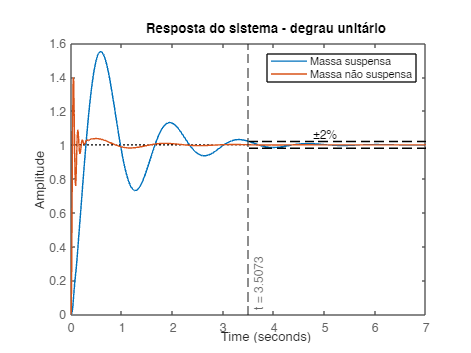


figure;

num1_ = [Cs*Cn, Ks*Cn + Kt*Cs, Ks*Kt];
den1_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn + Cs*Cn, Cs*Kt + Ks*Cn, Ks*Kt];
sys1 = tf(num1_, den1_);
step(sys1, 0:0.01:7);
hold on;

num2_ = [Ms*Cn, Cs*Cn + Ms*Kt, Ks*Cn + Cs*Kt, Ks*Kt];
den2_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn, Cs*Cn + Cs*Kt + Ks*Cn, Ks*Kt];
sys2 = tf(num2_, den2_);
step(sys2, 0:0.01:7);

title('Resposta do sistema - degrau unitário');

xline(3.5073, '--', {'t = 3.5073'}, 'LabelVerticalAlignment', 'bottom');

x_start = 3.5073;
x_end = 7;
y_value1 = 1.02;
y_value2 = 0.98;
ylim([0 1.6])

plot([x_start, x_end], [y_value1, y_value1], '--', 'Color', 'k');
plot([x_start, x_end], [y_value2, y_value2], '--', 'Color', 'k');
text((x_start + x_end) / 2, y_value1, '±2%', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');

legend('Massa suspensa', 'Massa não suspensa');


S1 = stepinfo(sys1)

S1 = struct with fields:
         RiseTime: 0.2162
    TransientTime: 3.5073
     SettlingTime: 3.5073
      SettlingMin: 0.7308
      SettlingMax: 1.5495
        Overshoot: 54.9537
       Undershoot: 0
             Peak: 1.5495
         PeakTime: 0.5697


S2 = stepinfo(sys2)

S2 = struct with fields:
         RiseTime: 0.0175
    TransientTime: 0.7172
     SettlingTime: 0.7172
      SettlingMin: 0.7532
      SettlingMax: 1.4176
        Overshoot: 41.7552
       Undershoot: 0
             Peak: 1.4176
         PeakTime: 0.0439



% resultados
amplitude_pico1 = S1.Peak;
tempo_pico1 = S1.PeakTime;
tempo_regime_permanente1 = S1.SettlingTime;
ultrapassagem1 = S1.Overshoot;

disp(' '); disp('Alterando coeficiente de amortecimento da suspensão para 1500 Ns/m:');

 
Alterando coeficiente de amortecimento da suspensão para 1500 Ns/m:


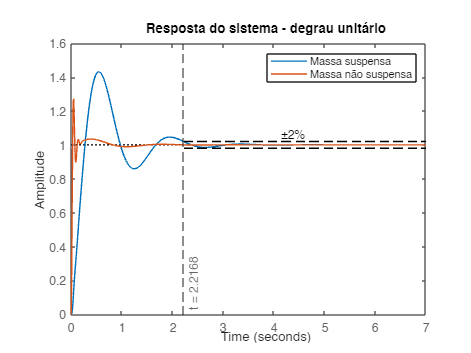


Cs = 1500; % [Ns/m]

figure;

num1_ = [Cs*Cn, Ks*Cn + Kt*Cs, Ks*Kt];
den1_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn + Cs*Cn, Cs*Kt + Ks*Cn, Ks*Kt];
sys1 = tf(num1_, den1_);
step(sys1, 0:0.01:7);
hold on;

num2_ = [Ms*Cn, Cs*Cn + Ms*Kt, Ks*Cn + Cs*Kt, Ks*Kt];
den2_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn, Cs*Cn + Cs*Kt + Ks*Cn, Ks*Kt];
sys2 = tf(num2_, den2_);
step(sys2, 0:0.01:7);
ylim([0 1.6])

title('Resposta do sistema - degrau unitário');

xline(2.2168, '--', {'t = 2.2168'}, 'LabelVerticalAlignment', 'bottom');

x_start = 2.2168;
x_end = 7;
y_value1 = 1.02;
y_value2 = 0.98;
ylim([0 1.6])

plot([x_start, x_end], [y_value1, y_value1], '--', 'Color', 'k');
plot([x_start, x_end], [y_value2, y_value2], '--', 'Color', 'k');
text((x_start + x_end) / 2, y_value1, '±2%', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');
legend('Massa suspensa', 'Massa não suspensa');


S1 = stepinfo(sys1)

S1 = struct with fields:
         RiseTime: 0.2023
    TransientTime: 2.2168
     SettlingTime: 2.2168
      SettlingMin: 0.8593
      SettlingMax: 1.4311
        Overshoot: 43.1104
       Undershoot: 0
             Peak: 1.4311
         PeakTime: 0.5464


S2 = stepinfo(sys2)

S2 = struct with fields:
         RiseTime: 0.0194
    TransientTime: 0.6175
     SettlingTime: 0.6175
      SettlingMin: 0.8954
      SettlingMax: 1.2852
        Overshoot: 28.5197
       Undershoot: 0
             Peak: 1.2852
         PeakTime: 0.0458


disp(' '); disp('Alterando coeficiente de amortecimento da suspensão para 2500 N/m:');

 
Alterando coeficiente de amortecimento da suspensão para 2500 N/m:


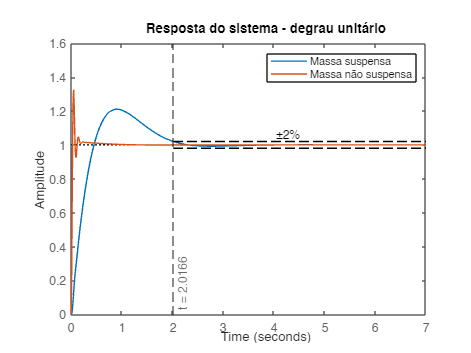


Ks = 2500; % [N/m]

figure;

num1_ = [Cs*Cn, Ks*Cn + Kt*Cs, Ks*Kt];
den1_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn + Cs*Cn, Cs*Kt + Ks*Cn, Ks*Kt];
sys1 = tf(num1_, den1_);
step(sys1, 0:0.01:7);
hold on;

num2_ = [Ms*Cn, Cs*Cn + Ms*Kt, Ks*Cn + Cs*Kt, Ks*Kt];
den2_ = [Ms*Mn, Ms*Cs + Ms*Cn + Mn*Cs, Ms*Ks + Ms*Kt + Ks*Mn, Cs*Cn + Cs*Kt + Ks*Cn, Ks*Kt];
sys2 = tf(num2_, den2_);
step(sys2, 0:0.01:7);
ylim([0 1.6])

title('Resposta do sistema - degrau unitário');

xline(2.0166, '--', {'t = 2.0166'}, 'LabelVerticalAlignment', 'bottom');

x_start = 2.0166;
x_end = 7;
y_value1 = 1.02;
y_value2 = 0.98;
ylim([0 1.6])

plot([x_start, x_end], [y_value1, y_value1], '--', 'Color', 'k');
plot([x_start, x_end], [y_value2, y_value2], '--', 'Color', 'k');
text((x_start + x_end) / 2, y_value1, '±2%', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');
legend('Massa suspensa', 'Massa não suspensa');



S1 = stepinfo(sys1)

S1 = struct with fields:
         RiseTime: 0.3324
    TransientTime: 2.0166
     SettlingTime: 2.0166
      SettlingMin: 0.9239
      SettlingMax: 1.2101
        Overshoot: 21.0096
       Undershoot: 0
             Peak: 1.2101
         PeakTime: 0.9118


S2 = stepinfo(sys2)

S2 = struct with fields:
         RiseTime: 0.0191
    TransientTime: 0.1665
     SettlingTime: 0.1665
      SettlingMin: 0.9041
      SettlingMax: 1.3325
        Overshoot: 33.2540
       Undershoot: 0
             Peak: 1.3325
         PeakTime: 0.0461



% resultados
amplitude_pico2 = S1.Peak;
tempo_pico2 = S1.PeakTime;
tempo_regime_permanente2 = S1.SettlingTime;
ultrapassagem2 = S1.Overshoot;

**Resultados:**

disp(' '); disp('Resultados:');

 
Resultados:


□Texto em negrito□


resultado_amp_pico = 100*(amplitude_pico2-amplitude_pico1)/amplitude_pico1;
resultado_t_pico = 100*(tempo_pico2-tempo_pico1)/tempo_pico1;
resultado_t_reg_perm = 100*(tempo_regime_permanente2-tempo_regime_permanente1)/tempo_regime_permanente1;
resultado_ultrapassagem = 100*(ultrapassagem2-ultrapassagem1)/ultrapassagem1;

disp(['Amplitude do pico: ' num2str(resultado_amp_pico) '%']);

Amplitude do pico: -21.906%


disp(['Tempo para atingir o pico de amplitude: ' num2str(resultado_t_pico) '%']);

Tempo para atingir o pico de amplitude: 60.0471%


disp(['Tempo para atingir regime permanente: ' num2str(resultado_t_reg_perm) '%']);

Tempo para atingir regime permanente: -42.5033%


disp(['Ultrapassagem: ' num2str(resultado_ultrapassagem) '%']);

Ultrapassagem: -61.7686%
